clear all
clc


TSSTA = readtable('SSTA.xlsx');

SWIO = readtable('SSTA.xlsx','sheet','SWIOSSTA')

SWIO = 4033×4 table
    Mon     Date       BM84       ICOADS
    ___    ______    _________    ______

     8     1671.6     -0.83461     NaN  
     9     1671.7     -0.65223     NaN  
    10     1671.8     -0.69827     NaN  
    11     1671.8     -0.91943     NaN  
    12     1671.9      -1.5055     NaN  
     1       1672     -0.58539     NaN  
     2     1672.1     -0.46828     NaN  
     3     1672.2     -0.79508     NaN  
     4     1672.2      -1.2477     NaN  
     5     1672.3      -1.6211     NaN  
     6     1672.4      -1.1583     NaN  
     7     1672.5     -0.60929     NaN  
     8     1672.6     -0.23541     NaN  
     9     1672.7     -0.17063     NaN  
    10     1672.8    -0.067773     NaN  
    11     1672.8    -0.066233     NaN  


TSST = readtable('SST.xlsx');

Date = TSSTA.Date;
ERSSTA=TSSTA.ERSSTv5;
TSSTA.ICOADSswio=SWIO.ICOADS;
HadISSTA=TSSTA.HadISST1;
HadSSTA=TSSTA.HadSST4;
SrCaA=TSSTA.SrCa;
SSTA2 = SrCaA/-0.084;

SD_a1 = (1/-0.061).*TSSTA.SrCaError;
SD_a2 = - ((SrCaA./((-0.061)^2))*0.01);
SSTA_Err = sqrt(SD_a1.^2+SD_a2.^2);

winds = readtable('Winds.xlsx','sheet','Sheet2');

climateindex =  readtable('Index.xlsx');
TSSTA.vwnd = winds.ICOADSvwnd;
TSSTA.vwnd2 = winds.x20CR;
TSSTA.WLS = SSTA2;
TSSTA.WLSerror = SSTA_Err;
TSSTA.ERSSTerror = TSST.ERSSTv3error;
TSSTA.Nino34 = climateindex.Nino34;
TSSTA.DMI = climateindex.DMI;
TSSTA.AMO = climateindex.AMO;

TSSTA.Mon = categorical(TSSTA.Mon);

yr = (1672:2006)';
yr_s = (1672:1:2007)';
yr_w = yr;
find (yr_s==1910); %1910
find (yr_s==1716); %1716
find (yr_s==1731); %31,32,33



% annual = table2array(TSSTA(:,2:end));
% 
% gap = (4:12:4024)';
% annualmean = zeros(size(yr,1),size(annual,2));
% for i=1:size(yr,1);
%     t=annual(gap(i):(gap(i+1)-1),:);
%     annualmean(i,:) = mean(t,1);
% i=i+1;
% end
% 
% annualmean(:,1)=yr;
% annualmean=array2table(annualmean,'VariableNames',{'Yr','SrCa','SrCaError','ERSSTv5','HadSST1','HadSST4','HadSST4error','OISSTv2','OISSTv2error','RMOS','ICOADS','vwnd','vwnd2','WLS','WLSerror','ERSSTerror','Nino34','DMI','AMO'});
% annualmean.WLS(45) = nan;
% annualmean.WLS(60:62) = nan;
% [annualmean.WLS,~] = fillmissing(annualmean.WLS,"linear","SamplePoints",annualmean.Yr); %fill gap 
% writetable(annualmean,'annualmean.xlsx')


gap = (4:12:4024)';
yr = (1672:2006)';

ASSTA2 = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=SSTA2(gap(i):(gap(i+1)-1));
    ASSTA2(i) = mean(t);
i=i+1;
end

ASSTA_Err = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=SSTA_Err(gap(i):(gap(i+1)-1));
    ASSTA_Err(i) = rms(t);
i=i+1;
end

AERSSTA_Err = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=TSST.ERSSTv3error(gap(i):(gap(i+1)-1));
    AERSSTA_Err(i) = rms(t);
i=i+1;
end


AERSSTA = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=ERSSTA(gap(i):(gap(i+1)-1));
    AERSSTA(i) = mean(t);
i=i+1;
end

AICOADSSSTA = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=TSSTA.ICOADS(gap(i):(gap(i+1)-1));
    if sum(~isnan(t))>10
       AICOADSSSTA(i) = mean(t,'omitnan');
    else
       AICOADSSSTA(i) = mean(t);
    end
    i=i+1;
end

% AERSSTAswio = zeros(size(yr,1),1);
% for i=1:size(yr,1);
%     t=TSSTA.ERSSTv5swio(gap(i):(gap(i+1)-1));
%     AERSSTAswio(i) = mean(t);
% i=i+1;
% end

AICOADSswio = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=TSSTA.ICOADSswio(gap(i):(gap(i+1)-1));
    if sum(~isnan(t))>10
       AICOADSswio(i) = mean(t,'omitnan');
    else
       AICOADSswio(i) = mean(t);
    end
    i=i+1;
end


Tsummer = vertcat(TSSTA((TSSTA.Mon=='1'),:),TSSTA((TSSTA.Mon=='2'),:),TSSTA((TSSTA.Mon=='3'),:),TSSTA((TSSTA.Mon=='12'),:));
Tsummer = sortrows(Tsummer,2);

% summer = table2array(Tsummer(:,2:end));
% 
% gap = (1:4:1345)';
% summermean = zeros(336,size(summer,2));
% for i=1:336;
%     t=summer(gap(i):(gap(i+1)-1),:);
%     summermean(i,:) = mean(t,1);
% i=i+1;
% end
% summermean(:,1)=yr_s;
% summermean=array2table(summermean,'VariableNames',{'Yr','SrCa','SrCaError','ERSSTv5','HadSST1','HadSST4','HadSST4error','OISSTv2','OISSTv2error','RMOS','ICOADS','vwnd','vwnd2','WLS','WLSerror','ERSSTerror','Nino34','DMI','AMO'});
% 
% summermean.WLS(45) = nan;
% summermean.WLS(60:62) = nan;
% [summermean.WLS,~] = fillmissing(summermean.WLS,"linear","SamplePoints",summermean.Yr); %fill gap 
% writetable(summermean,'summermean.xlsx')


gap = (1:4:1345)';

summerERSST= zeros(336,1);
for i=1:336;
    t=Tsummer.ERSSTv5(gap(i):(gap(i+1)-1));
    summerERSST(i) = mean(t);
i=i+1;
end

summerERSSTA_Err = zeros(size(yr,1),1);
for i=1:336;
    t=Tsummer.ERSSTerror(gap(i):(gap(i+1)-1));
    summerERSSTA_Err(i) = rms(t);
i=i+1;
end

summerICOADS= zeros(336,1);
for i=1:336;
    t=Tsummer.ICOADS(gap(i):(gap(i+1)-1));
    if sum(~isnan(t))>1
       summerICOADS(i) = mean(t,'omitnan');
    else
       summerICOADS(i) = mean(t);
    end
i=i+1;
end

summerWLS = zeros(336,1);
for i=1:336;
    t=Tsummer.WLS(gap(i):(gap(i+1)-1));
    summerWLS(i) = mean(t,'omitnan');
i=i+1;
end

summerWLSerror = zeros(336,1);
for i=1:336;
    t=Tsummer.WLSerror(gap(i):(gap(i+1)-1));
    summerWLSerror(i) = rms(t,'omitnan');
end

summervwnd = zeros(336,1);
for i=1:336;
    t=Tsummer.vwnd(gap(i):(gap(i+1)-1));
    if sum(~isnan(t))>2
       summervwnd(i) = mean(t,'omitnan');
    else
       summervwnd(i) = mean(t);
    end
i=i+1;
end


summervwnd2 = zeros(336,1);
for i=1:336;
    t=Tsummer.vwnd2(gap(i):(gap(i+1)-1));
    if sum(~isnan(t))>2
       summervwnd2(i) = mean(t,'omitnan');
    else
       summervwnd2(i) = mean(t);
    end
i=i+1;
end


Twinter = vertcat(TSSTA((TSSTA.Mon=='6'),:),TSSTA((TSSTA.Mon=='7'),:),TSSTA((TSSTA.Mon=='8'),:),TSSTA((TSSTA.Mon=='9'),:));
Twinter = sortrows(Twinter,2);
Twinter = Twinter(3:1342,:);
%winter = table2array(Twinter(:,2:end));
% 
% gap = (1:4:1341)';
% wintermean = zeros(335,size(winter,2));
% for i=1:335;
%     t=winter(gap(i):(gap(i+1)-1),:);
%     wintermean(i,:) = mean(t,1);
% i=i+1;
% end
% wintermean(:,1)=yr_w;
% wintermean=array2table(wintermean,'VariableNames',{'Yr','SrCa','SrCaError','ERSSTv5','HadSST1','HadSST4','HadSST4error','OISSTv2','OISSTv2error','RMOS','ICOADS','vwnd','vwnd2','WLS','WLSerror','ERSSTerror','Nino34','DMI','AMO'});
% 
% wintermean.WLS(45) = nan;
% wintermean.WLS(60:62) = nan;
% [wintermean.WLS,~] = fillmissing(wintermean.WLS,"linear","SamplePoints",wintermean.Yr); %fill gap 
% writetable(wintermean,'wintermean.xlsx')



gap = (1:4:1341)';

winterERSST = zeros(335,1);
for i=1:335;
    t=Twinter.ERSSTv5(gap(i):(gap(i+1)-1));
    winterERSST(i) = mean(t,'omitnan');
i=i+1;
end
% 
% winterERSSTswio = zeros(335,1);
% for i=1:335;
%     t=Twinter.ERSSTv5swio(gap(i):(gap(i+1)-1));
%     winterERSSTswio(i) = mean(t,'omitnan');
% i=i+1;
% end


winterERSSTA_Err = zeros(size(yr,1),1);
for i=1:335;
    t=Twinter.ERSSTerror(gap(i):(gap(i+1)-1));
    winterERSSTA_Err(i) = rms(t);
i=i+1;
end

winterICOADS = zeros(335,1);
for i=1:335;
    t=Twinter.ICOADS(gap(i):(gap(i+1)-1));
    if sum(~isnan(t))>1
       winterICOADS(i) = mean(t,'omitnan');
    else
       winterICOADS(i) = mean(t);
    end
i=i+1;
end

winterICOADSswio = zeros(335,1);
for i=1:335;
    t=Twinter.ICOADSswio(gap(i):(gap(i+1)-1));
    if sum(~isnan(t))>1
       winterICOADSswio(i) = mean(t,'omitnan');
    else
       winterICOADSswio(i) = mean(t);
    end
i=i+1;
end

winterWLS = zeros(335,1);
for i=1:335;
    t=Twinter.WLS(gap(i):(gap(i+1)-1));
    winterWLS(i) = mean(t,'omitnan');
i=i+1;
end

winterWLSerror = zeros(335,1);
for i=1:335;
    t=Twinter.WLSerror(gap(i):(gap(i+1)-1));
    winterWLSerror(i) = rms(t,'omitnan');
i=i+1;
end

ASSTA2(45) = nan;
ASSTA2(60:62) =nan;
summerWLS(45) = nan;
summerWLS(60:62) =nan;
winterWLS(45) = nan;
winterWLS(60:62) =nan;

[ASSTA2,~] = fillmissing(ASSTA2,"linear","SamplePoints",yr); %fill gap 
[summerWLS,~] = fillmissing(summerWLS,"linear","SamplePoints",yr_s); %fill gap 
[winterWLS,~] = fillmissing(winterWLS,"linear","SamplePoints",yr_w); %fill gap 


k=1;
[m1,n1]=butter(5,(1/10)/(0.5*k),'low');
ASSTA_10 = filtfilt(m1,n1,ASSTA2);
AERSSTA_10 = filtfilt(m1,n1,AERSSTA(184:end));
summerSSTA_10 = filtfilt(m1,n1,summerWLS);
summerERSSTA_10 = filtfilt(m1,n1,summerERSST(184:end));
winterSSTA_10 = filtfilt(m1,n1,winterWLS);
winterERSSTA_10 = filtfilt(m1,n1,winterERSST(184:end));
summervwnd2_10 = filtfilt(m1,n1,summervwnd2(166:end));

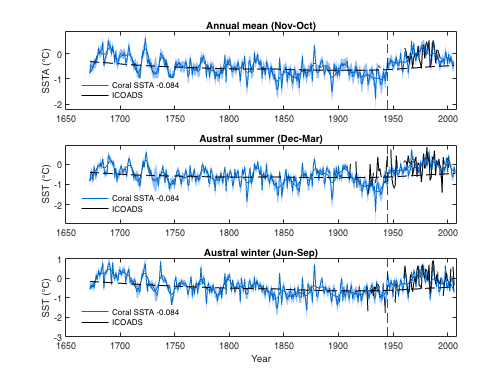

clf
subplot(3,1,1)
hold on 
ASSTA_Err2 = vertcat(ASSTA2+ASSTA_Err,flipud(ASSTA2-ASSTA_Err));
%AERSSTA_Err1 = vertcat(AERSSTA(184:end)+AERSSTA_Err(184:end),flipud(AERSSTA(184:end)-AERSSTA_Err(184:end)));
Apatch_date = vertcat(yr,flipud(yr));
%Apatch_date2 = vertcat(yr(184:end),flipud(yr(184:end)));
plot(yr,ASSTA2,'LineWidth',1)
%plot(yr,AERSSTA,'LineWidth',1)
plot(yr,AICOADSSSTA,'k-','LineWidth',1)
plot(yr,ASSTA_10,'LineWidth',1,'color',[0 104 160]/256)
%plot(yr(184:end),AERSSTA_10,'LineWidth',1,'color',[160 94 0]/256)
patch(Apatch_date,ASSTA_Err2,[0 94 240]/256,'Edgecolor','none','Facealpha',0.4)
%patch(Apatch_date2,AERSSTA_Err1,[240 94 0]/256,'Edgecolor','none','Facealpha',0.4)
LT_A = trenddecomp(ASSTA2);
plot(yr,LT_A,'--k')
xline(1945,'--k')
set(gca,'XLim',[1650 2008])
lg = legend('Coral SSTA -0.084','ICOADS','Location','best');
box on
set(lg,'box','off')
ylabel('SSTA (°C)')
title('Annual mean (Nov-Oct)')

subplot(3,1,2)
hold on 

plot(yr_s,summerWLS,'-','LineWidth',1)
summerWLSerror2 = vertcat(summerWLS+summerWLSerror,flipud(summerWLS-summerWLSerror));
%summerERSSTA_Err1 = vertcat(summerERSST(184:end)+summerERSSTA_Err(184:end),flipud(summerERSST(184:end)-summerERSSTA_Err(184:end)));
patch_date_summer = vertcat(yr_s,flipud(yr_s));
%patch_date_summer2 = vertcat(yr_s(184:end),flipud(yr_s(184:end)));
%plot(yr_s,summerERSST,'-','LineWidth',1)
plot(yr_s,summerICOADS,'-','LineWidth',1,'color',[0 0 0])
plot(yr_s,summerSSTA_10,'LineWidth',1,'color',[0 104 160]/256)
%plot(yr_s(184:end),summerERSSTA_10,'LineWidth',1,'color',[160 94 0]/256)
patch(patch_date_summer,summerWLSerror2,[0 94 240]/256,'Edgecolor','none','Facealpha',0.4)
%patch(patch_date_summer2,summerERSSTA_Err1,[240 94 0]/256,'Edgecolor','none','Facealpha',0.4)
LT_S = trenddecomp(summerWLS);
plot(yr_s,LT_S,'--k')
xline(1945,'--k')
lg = legend('Coral SSTA -0.084','ICOADS','Location','best');
set(lg,'box','off')
box on 
title('Austral summer (Dec-Mar)')
ylabel('SST (°C)')
set(gca,'XLim',[1650 2008])

subplot(3,1,3)
hold on 

plot(yr_w,winterWLS,'-','LineWidth',1)
winterWLSerror2 = vertcat(winterWLS+winterWLSerror,flipud(winterWLS-winterWLSerror));
%winterERSSTA_Err1 = vertcat(winterERSST(184:end)+winterERSSTA_Err(184:end),flipud(winterERSST(184:end)-winterERSSTA_Err(184:end)));
%plot(yr_w,winterERSST,'-','LineWidth',1)
plot(yr_w,winterICOADS,'-','LineWidth',1,'color',[0 0 0])
plot(yr_w,winterSSTA_10,'LineWidth',1,'color',[0 104 160]/256)
%plot(yr_w(184:end),winterERSSTA_10,'LineWidth',1,'color',[160 94 0]/256)
patch_date_winter = vertcat(yr_w,flipud(yr_w));
%patch_date_winter2 = vertcat(yr_w(184:end),flipud(yr_w(184:end)));
patch(patch_date_winter,winterWLSerror2,[0 94 240]/256,'Edgecolor','none','Facealpha',0.4)
%patch(patch_date_winter2,winterERSSTA_Err1,[240 94 0]/256,'Edgecolor','none','Facealpha',0.4)
LT_W = trenddecomp(winterWLS);
plot(yr_w,LT_W,'--k')
xline(1945,'--k')
set(gca,'XLim',[1650 2008])
set(gca,'YLim',[-3 1])
lg = legend('Coral SSTA -0.084','ICOADS','Location','best');
set(lg,'box','off')
box on 
title('Austral winter (Jun-Sep)')
ylabel('SST (°C)')
xlabel('Year')

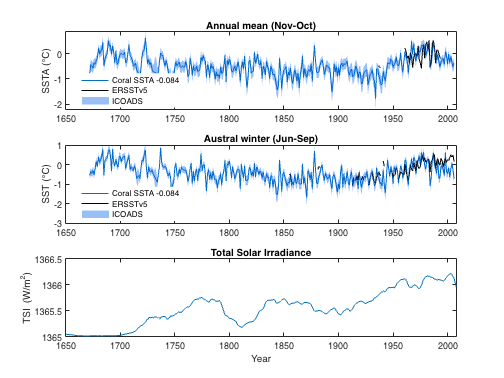

clf
subplot(3,1,1)
hold on 
ASSTA_Err2 = vertcat(ASSTA2+ASSTA_Err,flipud(ASSTA2-ASSTA_Err));
Apatch_date = vertcat(yr,flipud(yr));
plot(yr,ASSTA2,'LineWidth',1)
%plot(yr,AERSSTAswio,'LineWidth',1)
plot(yr,AICOADSSSTA,'k-','LineWidth',1)
patch(Apatch_date,ASSTA_Err2,[0 94 240]/256,'Edgecolor','none','Facealpha',0.4)

set(gca,'XLim',[1650 2008])
lg = legend('Coral SSTA -0.084','ERSSTv5','ICOADS','Location','best');
box on
set(lg,'box','off')
ylabel('SSTA (°C)')
title('Annual mean (Nov-Oct)')


subplot(3,1,2)
hold on 

plot(yr_w,winterWLS,'-','LineWidth',1)
winterWLSerror2 = vertcat(winterWLS+winterWLSerror,flipud(winterWLS-winterWLSerror));
%plot(yr,winterERSSTswio,'LineWidth',1)
plot(yr_w,winterICOADSswio,'-','LineWidth',1,'color',[0 0 0])
patch_date_winter = vertcat(yr_w,flipud(yr_w));
patch(patch_date_winter,winterWLSerror2,[0 94 240]/256,'Edgecolor','none','Facealpha',0.4)
set(gca,'XLim',[1650 2008])
set(gca,'YLim',[-3 1])
lg = legend('Coral SSTA -0.084','ERSSTv5','ICOADS','Location','best');
set(lg,'box','off')
box on 
title('Austral winter (Jun-Sep)')
ylabel('SST (°C)')


subplot(3,1,3)
TSI = readtable('TSI.xlsx');
plot(TSI.Yr, movmean(TSI.TSI,10))
title('Total Solar Irradiance')
set(gca,'xlim',[1650 2008])
ylabel('TSI (W/m^2)')
xlabel('Year')


gap = (4:12:4024)';
yr = (1672:2006)';



max(ASSTA2)-min(ASSTA2)
max(summerWLS)-min(summerWLS)
max(winterWLS)-min(winterWLS)

fitlm(yr_s(239:end),summerWLS(239:end))
0.012483*(yr_s(end)-yr_s(239))
0.0014279*(yr_s(end)-yr_s(239))
fitlm(yr_w(239:end),winterWLS(239:end))
0.0088602*(yr_w(end)-yr_w(239))
0.0015143*(yr_w(end)-yr_w(239))


clf
subplot(3,1,1)
hold on 
yyaxis left
plot(yr_s,summerWLS,'--')
plot(yr_s,summerSSTA_10,'-','LineWidth',1,'color',[0 104 190]/256)
patch(patch_date_summer,summerWLSerror2,[0 94 240]/256,'Edgecolor','none','Facealpha',0.4)
ylabel('SSTA (°C)')

yyaxis right
plot(yr_s,summervwnd2,'.--k')
plot(yr_s(166:end),summervwnd2_10,'-k','linewidth',1)
lg = legend('','Coral SSTA -0.084','','','20CR meridional wind ','Location','best');
set(lg,'box','off')
box on
ylabel('Wind speed (m/s)')
set(gca,'XLim',[1650 2008])
ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';

subplot(3,1,2)
MC = readtable('monthly reconsMC.xlsx','VariableNamingRule','preserve','Sheet','84slope');
coralSST_centred = MC.SST;
gap = (4:12:4024)';
yr = (1672:2006)';
Scoral = zeros(335,1);
for i=1:335;
    t=coralSST_centred(gap(i):(gap(i+1)-1));
    Scoral(i) = max(t)- min(t);
i=i+1;
end
hold on
plot(yr,Scoral,'linewidth',0.5,'LineStyle','--','color',[0.5 0.5 0.5])
plot(yr,movmean(Scoral,5),'linewidth',1,'color',[0 0 0])
lg = legend('','SST seasonal amplitude','Location','best');
set(lg,'box','off')
box on
ylabel('Seasonality (°C)')
set(gca,'XLim',[1650 2008])
subplot(3,1,3)
IWM = readtable('IWM recons');
plot(IWM.Age_aAD_CE_, IWM.SST_1_Anomaly__C_)

lg = legend('IWM reconstruction','Location','best');
set(lg,'box','off')
box on
ylabel('SSTA(°C)')
xlabel('Year')
set(gca,'XLim',[1650 2008])

k=1;
[m1,n1]=butter(5,(1/15)/(0.5*k),'low');
ASSTA_10 = filtfilt(m1,n1,ASSTA2);
AERSSTA_10 = filtfilt(m1,n1,AERSSTA(184:end));
summerSSTA_10 = filtfilt(m1,n1,summerWLS);
summerERSSTA_10 = filtfilt(m1,n1,summerERSST(184:end));
winterSSTA_10 = filtfilt(m1,n1,winterWLS);
winterERSSTA_10 = filtfilt(m1,n1,winterERSST(184:end));
summervwnd2_10 = filtfilt(m1,n1,summervwnd2(166:end));

[r p] = corr(summervwnd2_10,summerSSTA_10(166:end))
n =length(summerSSTA_10(166:end));
r1 = autocorr(summerSSTA_10(166:end),1);
r1= r1(2);
r2=autocorr(summervwnd2_10,1);
r2 = r2(2);
nadj = n.*(1-r1.*r2)./(1+r1.*r2)
t_stat = r * sqrt((nadj - 2) / (1 - r^2));
p_adj = 2 * (1 - tcdf(abs(t_stat), nadj - 2))

k=1;
[m1,n1]=butter(2,([1/7 1/2.01])/(0.5*k),'bandpass');
ASSTA_10 = filtfilt(m1,n1,ASSTA2);
WSSTA_10 = filtfilt(m1,n1,winterWLS);
ENSO_10 = filtfilt(m1,n1,annualmean.Nino34(184:end));
DMI_10 = filtfilt(m1,n1,annualmean.DMI(184:end));
% ENSO_10w = filtfilt(m1,n1,wintermean.Nino34(184:end));
% DMI_10w = filtfilt(m1,n1,wintermean.DMI(184:end));
IOD=readtable('IOD.xls','sheet','sheet1');
DMICoral = IOD.DMICoral;
DMICoal_10 = filtfilt(m1,n1,IOD.DMICoral);


clf('reset')
subplot(2,1,1)
hold on
plot(yr,ASSTA_10)
plot(yr,WSSTA_10)
plot(yr(184:end),ENSO_10)
plot(yr(184:end),DMI_10)
box on
lg =legend('SSTA','winter SSTA','Nino3.4','DMI');
set(lg,'box','off')
set(gca,'xlim',[1840 2050])
ylabel('SSTA (°C)')

subplot(2,1,2)
hold on
[r p] =movcorr(ASSTA_10(184:end),ENSO_10,21);
r(1:10) = nan;
r(end-9:end) = nan;
plot(yr(184:end),r,':k')
insig1 = find(p>0.1);
r(insig1) = nan;
plot(yr(184+10:end-10),r(11:end-10),'-k')


[r p] =movcorr(ASSTA_10(184:end),DMI_10,21);
r(1:10) = nan;
r(end-9:end) = nan;
plot(yr(184:end),r,':r')
insig1 = find(p>0.1);
r(insig1) = nan;
plot(yr(184+10:end-10),r(11:end-10),'-r')


[r p] =movcorr(WSSTA_10(184:end),ENSO_10,21);
r(1:10) = nan;
r(end-9:end) = nan;
plot(yr(184:end),r,':k')
insig1 = find(p>0.1);
r(insig1) = nan;
plot(yr(184+10:end-10),r(11:end-10),'--k')


[r p] =movcorr(WSSTA_10(184:end),DMI_10,21);
r(1:10) = nan;
r(end-9:end) = nan;
plot(yr(184:end),r,':r')
insig1 = find(p>0.1);
r(insig1) = nan;
plot(yr(184+10:end-10),r(11:end-10),'--r')

[r p] =movcorr(ENSO_10,DMI_10,21);
r(1:10) = nan;
r(end-9:end) = nan;
insig1 = find(p>0.1);
r(insig1) = nan;
plot(yr(184+10:end-10),r(11:end-10),'-b')

box on
lg =legend('','SSTA-Nino3.4','','SSTA-DMI','','winterSSTA-Nino3.4','','winterSSTA-DMI','DMI-ENSO');
set(lg,'box','off')
set(gca,'xlim',[1840 2050])
ylabel('Correlation Coefficient')
xlabel('Year')

clf('reset')
subplot(2,1,1)
hold on
plot(yr,ASSTA_10)
plot(yr,WSSTA_10)
plot(IOD.Year,DMICoal_10)
box on
lg =legend('SSTA','winter SSTA','DMI');
set(lg,'box','off')
set(gca,'xlim',[1840 2050])
ylabel('SSTA (°C)')
subplot(2,1,2)
hold on
[r p] =movcorr(ASSTA_10(175:323),DMICoal_10,21);
r(1:10) = nan;
r(end-9:end) = nan;
plot(yr(175:323),r,':k')
insig1 = find(p>0.1);
r(insig1) = nan;
plot(yr(175+10:323-10),r(11:end-10),'-k')


[r p] =movcorr(WSSTA_10(175:323),DMICoal_10,21);
r(1:10) = nan;
r(end-9:end) = nan;
plot(yr(175:323),r,':k')
insig1 = find(p>0.1);
r(insig1) = nan;
plot(yr(175+10:323-10),r(11:end-10),'--k')


box on
lg =legend('','SSTA-DMI','','winterSSTA-DMI');
set(lg,'box','off')
set(gca,'xlim',[1840 2050])
ylabel('Correlation Coefficient')
xlabel('Year')


nino34 = readtable('nino34.xlsx');
nino34_10 = filtfilt(m1,n1,nino34.HadSST2itot);

clf
subplot(2,1,1)
yyaxis left
hold on
plot(yr,ASSTA_10)
plot(yr,WSSTA_10)
plot(nino34.age,nino34_10,'color',[0.6 0.3 0.3],'linestyle','-')
set(gca,'xlim',[1671 2008])

ylabel('SSTA (°C)')
yyaxis right
plot(nino34.age,movstd(nino34_10,11))
box on
lg =legend('SSTA','Winter SSTA','Nino3.4','Nino3.4 Variance');
set(lg,'box','off')
set(gca,'ylim',[-1 1.2])
set(gca,'xlim',[1650 2100])
ylabel('RSD(°C)')
xlabel('Year')

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';

subplot(2,1,2)
hold on
[r p] =movcorr(ASSTA_10(1:324),flip(nino34_10(1:324)),21);
r(1:10) = nan;
r(end-9:end) = nan;
plot(yr(1:324),r,':k')
insig1 = find(p>0.1);
r(insig1) = nan;
plot(yr(11:324-15),r(11:324-15),'-k')

[r p] =movcorr(WSSTA_10(1:324),flip(nino34_10(1:324)),21);
r(1:10) = nan;
r(end-9:end) = nan;
plot(yr(1:324),r,':r')
insig1 = find(p>0.1);
r(insig1) = nan;
plot(yr(11:324-15),r(11:324-15),'-r')
box on
lg =legend('','SSTA-Nino3.4','','winter SSTA-Nino3.4');
set(lg,'box','off')
set(gca,'xlim',[1650 2100])
ylabel('Correlation Coefficient')
xlabel('Year')


clf('reset')

subplot(2,1,1)
k=1;
[m1,n1]=butter(5,([1/40 1/10])/(0.5*k),'bandpass');
ASSTA_20 = filtfilt(m1,n1,ASSTA2);
WSSTA_20 = filtfilt(m1,n1,winterWLS);
IODCoral_20 = filtfilt(m1,n1,IOD.DMICoral);
hold on
plot(yr,ASSTA_20)
plot(yr,WSSTA_20)
plot(IOD.Year,IODCoral_20,'-k')
box on
lg =legend('SSTA','WinterSSTA','Coral DMI');
set(lg,'box','off')
ylabel('SSTA (°C)')
set(gca,'xlim',[1650 2100])


subplot(2,1,2)
k=1;
[m1,n1]=butter(5,([1/30 1/10])/(0.5*k),'bandpass');
ASSTA_20 = filtfilt(m1,n1,ASSTA2);
WSSTA_20 = filtfilt(m1,n1,winterWLS);
DMI_20 = filtfilt(m1,n1,annualmean.DMI(184:end));
hold on
plot(yr,ASSTA_20)
plot(yr,WSSTA_20)
plot(yr(184:end),DMI_20,'-k')
box on
lg =legend('SSTA','Winter SSTA','ERSSTv5 DMI');
set(lg,'box','off')
ylabel('SSTA (°C)')
xlabel('Year')
set(gca,'xlim',[1650 2100])


k=1;
[m1,n1]=butter(5,([1/20 1/10])/(0.5*k),'bandpass');

nino34 = readtable('nino34.xlsx');
nino34_10 = filtfilt(m1,n1,nino34.HadSST2itot);

clf
yyaxis left
hold on
plot(yr,ASSTA_20)
plot(yr,WSSTA_20)
plot(nino34.age,nino34_10,'color',[0.6 0.3 0.3],'linestyle','-')
set(gca,'xlim',[1671 2008])

ylabel('SSTA (°C)')
yyaxis right
hold on
[r p] =movcorr(ASSTA_20(1:324),flip(nino34_10(1:324)),31);
plot(yr(1:324),r,'--k')
insig1 = find(p>0.1);
r(insig1) = nan;
plot(yr(11:324-15),r(11:324-15),'-k')

[r p] =movcorr(WSSTA_20(1:324),flip(nino34_10(1:324)),31);
plot(yr(1:324),r,'--r')
insig1 = find(p>0.1);
r(insig1) = nan;
plot(yr(11:324-15),r(11:324-15),'-r')

box on
lg =legend('SSTA','Winter SSTA','Nino3.4','','SSTA-Nino3.4','','winter SSTA-Nino3.4');
set(lg,'box','off')
set(gca,'xlim',[1650 2100])
ylabel('Correlation Coefficient')
xlabel('Year')

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';


AMO =readtable('AMO.xlsx');
k=1;
[m1,n1]=butter(5,(1/20)/(0.5*k),'low');
ASSTA_30 = filtfilt(m1,n1,ASSTA2);
summer_30 = filtfilt(m1,n1,summerWLS);
winter_30 = filtfilt(m1,n1,winterWLS);
clf
hold on
plot(yr_s,summer_30)
plot(yr,ASSTA_30,'k')

yyaxis right
plot(AMO.Yr,AMO.AMO)



% MOVCORR Moving Pearson product-moment correlation coefficient r. This is
% basically a wrapper to MOVSUM and the low-memory overhead computation of r.
% See second formula in 
%   https://en.wikipedia.org/wiki/Pearson_correlation_coefficient#For_a_sample
%
% @Synopsis
%   r = MOVCORR(x, y, k) computes r for x and y over a centered window specified
%   by k.
%
%   MOVCORR(x, y, k, missing) specifies how to treats NaNs.
%
%   MOVSUM(...,'Endpoints',endpoints) controls how the start/end of the vectors
%   are handled.
%
%   [r, p] = MOVSUM(...) also returns the p-values for each computed r.
%
%   [r, p] = MOVSUM(...,'Tail',tail) controls what kind of hypothesis test is
%   used to compute the p-values.
%
% @Input
%   x, y (required)
%     m x 1 column vectors with the data to correlate.
%
%   k (required)
%      Positive integer scalar with the window size or 1x2 array of non-negative
%      integer scalars [nB, nF] with backward & forward samples for the window.
%      If k is a scalar and is even, the window is centered on the current &
%      previous sample, e.g. ranges from i-k/2 to i+k/2-1. If k is a vector the
%      window ranges from i-nB to i+nF.
%
%   missing (optional)
%     Flag of what to do with missing values. Either 'includenan' or 'omitnan'.
%     For 'omitnan' the r values are computed pairwise, resembling the behavior
%     of CORR(...,'Rows','pairwise') - but of course much faster.
%     DEFAULT: 'includenan'
%
%   'Endpoints',endpoints (Name/value)
%     Specifies how to handle the start/end of the vectors. Either a numeric or
%     logical scalar or 'shrink', 'fill' or 'discard'. Be aware that using
%     arbitrary numeric values does not really make sense in this setting (as
%     the correlation coefficient is bound between -1 and 1). Moreover, when
%     using numeric/logical endpoints, the according p-values are set to NaN.
%     This result in unexpected NaNs: If missing=='omitnan' and endpoints is
%     numeric, then p will contain NaNs at the endpoints, despite r beeing
%     finite.
%     DEFAULT: 'shrink'
%
%   'Tail',tail (Name/value)
%     Specifies the hypothesis with which the p-values are computed. Either
%     'both', 'left' or 'right'. See CORR for more details.
%     DEFAULT: 'both'
%
%   'MinN',nMin (Name/value)
%     Positive integer scalar with the minimum number of non-NaN values in a
%     local window required for computation of r. If a window does not have the
%     required number of values, r is not computed (e.g. set to NaN). 'MinN' has
%     to be equal or smaller than the window length specified by k. This
%     option is ignored if missing=='includenan'. Setting 'MinN' > 1 when using 
%     'Endpoints'=='shrink' may cause the values at the borders to be NaN,
%     despite the 'shrink' option.
%     DEFAULT: 1 (always compute r)
%
% @Output
%   r
%     m x 1 column vector with the local Pearson correlation coefficients for
%     each mutual sample in x and y.
%
%   p
%     m x 1 column vector with the p-values for the local Pearson correlation
%     coefficients.
%
%   n
%     The number of non-NaN values in each local window. If
%     missing=='includenan', this is a scalar equal to the window size. If
%     missing=='omitnan', this is an m x 1 column vector with the number of
%     non-NaN elements in each local window. This can be used to compute the
%     degrees-of-freedom for partial correlations.
%
% @Remarks
%   - For more detailed info on the inputs & syntax see MOVSUM.
%
% @Dependencies
%   none
%
% See also CORR, MOVSUM
%
% ML-FEX ID:65342
%
% @Changelog
%   2017-12-07 (DJM): 
%     - [RELEASE] Golden.
%     - [MOD] Computation of r with NaNs + 'omitnan' now gives same results as
%       CORR(...,'Rows','pairwise').
%   2017-12-11 (DJM): 
%     - [ADD] Name-value input 'Tail' and according p-value output.
%     - [MOD] Now uses INPUTPARSER. Changes error messages for invalid inputs.
%     - [FIX] Erroneous window size computation when using k = [nB, nF].
%     - [FIX] Complex output when using numeric endpoints.
%   2017-12-12 (DJM): 
%     - [ADD] Output n.
%   2017-12-14 (DJM): 
%     - [ADD] Name-value input 'MinN'.
%     - [MOD] Now returns NaN for zero-variances, to be consistent with CORR.
%

function [r, p, n] = movcorr(x, y, k, varargin)
%% Parse inputs
[x, y, k, missing, endpoints, tail, nMin, n] ...
    = parseInputs(x, y, k, varargin);
isNumericEndpoints = ~ischar(endpoints);
if isNumericEndpoints
	% With numeric/logical endpoints, we set the method to 'fill' and set the
	% values in the end, to avoid problems when using MOVSUM on x & x^2.
	endpointVals = endpoints;
	endpoints    = 'fill';
end
%% Assemble lambda function for MOVSUM
movingSum = @(v) movsum(v, k, missing, 'Endpoints',endpoints);
%% Compute sums
sumX = movingSum(x);
sumY = movingSum(y);
%% Compute r
% Use SQRT in denominator on x & y separately to avoid under/overflow.
r = (n .* movingSum(x.*y) - sumX.*sumY) ...
 ./ (sqrt(n .* movingSum(x.^2) - sumX.^2) .* sqrt(n .* movingSum(y.^2) - sumY.^2));
%% Handle values > +/-1
% Use same method as CORR to be consistent. This will cause INFs to be NaN...
% which might be argued upon.
isExceeding = abs(r) > 1;
r(isExceeding) = r(isExceeding) ./ abs(r(isExceeding));
%% Remove invalid windows
if strcmp(missing, 'omitnan')
	r(n < nMin) = NaN; % n is vector if missing=='omitnan'.
end
%% Compute p-values
if nargout() > 1
	p = computePvalues(r, n, tail);
end
%% Handle endpoints
if isNumericEndpoints
	ids = [1 : k(1), length(r) - k(2) + 1 : length(r)];
	r(ids) = endpointVals;
	p(ids) = NaN;
end
end % MAINFUNCTION
%% SUBFUNCTION: parseInputs
% PARSEINPUTS Parses the inputs to the main function.
%
% @Input
%   x,y,k (required)
%     Required main function inputs.
%
%   varArgIn (required)
%     Optional main function inputs (VARARGIN).
%
% @Output
%   x,y,k
%     Required main function inputs.
%
%   missing
%     Optional main function input.
%
%   endpoints,tail,nMin
%     Name-value main function inputs.
%
%   n
%     Window length (based on k). If isAnyNan==true this is a mx1 vector with
%     the local window sizes for finite-values.
%
function [x, y, k, missing, endpoints, tail, nMin, n] = parseInputs(x, y, k,...
                                                                    varArgIn)
%% >SUB: Init
% Valid enumeration vals. First is used as default.
VALID_MISS    = {'includenan', 'omitnan'};
VALID_ENDPNTS = {'shrink', 'discard', 'fill'};
VALID_TAILS   = {'both', 'left', 'right'};
% Error messages - partly resembles errors from MOVSUM.
ERR_BASE_ID = 'DJM:IOFailure';
ERR_MSG_X_Y_DIM         = '''x'' and ''y'' have to be of equal size.';
ERR_MSG_K_INVALID       = '''k'' must be a finite scalar positive integer or 2-element vector of finite nonnegative integers.';
ERR_MSG_MISS_INVALID    = '''missing'' value must be ''omitnan'' or ''includenan''.';
ERR_MSG_ENDPNTS_INVALID = '''Endpoints'' value must be ''shrink'', ''discard'', ''fill'', or a numeric or logical scalar.';
ERR_MSG_TAIL_INVALID    = '''Tail'' value must be ''both'', ''left'' or ''right''.';
ERR_MSG_MIN_N_INVALID   = '''MinN'' has to be equal or smaller than the window length given by ''k''.';
ERR_MSG_MIN_N_IGNORED   = '''MinN'' is ignored with option ''includenan''.';
ERR_MSG_MIN_N_SHRINKED  = '''MinN'' may cause unexpected NaNs at the borders with option ''shrink''.';
%% >SUB:  Create INPUTPARSER
IP = inputParser();
IP.StructExpand  = true;
IP.KeepUnmatched = false;
%% >SUB: Set up validation functions
validateNumCol          = @(v)validateattributes(v,{'numeric'},{'column'});
validateNumScaFinIntPos = @(v)validateattributes(v,{'numeric'},{'scalar','finite','integer','positive'});
validateNumVecFinIntNN  = @(v)validateattributes(v,{'numeric'},{'vector','finite','integer','nonnegative'});
validateCharOrNumRow    = @(v)validateattributes(v,{'char','numeric','logical'},{'row'});
validateCharRow         = @(v)validateattributes(v,{'char'},{'scalartext'});
%% >SUB: Define inputs
IP.addRequired( 'x'        , validateNumCol);
IP.addRequired( 'y'        , validateNumCol);
IP.addRequired( 'k'        , validateNumVecFinIntNN);
IP.addParameter('Endpoints', VALID_ENDPNTS{1}, validateCharOrNumRow);
IP.addParameter('Tail'     , VALID_TAILS{1}  , validateCharRow);
IP.addParameter('MinN'     , 1               , validateNumScaFinIntPos);
%% >SUB: Parse 'missing' if given
% This is an optional input which can be ommitted and thus cannot be handled by
% INPUTPARSER.
isDefault = isempty(varArgIn) || ~ischar(varArgIn{1}) ...
         || ismember(varArgIn{1}, {'Endpoints', 'Tail', 'MinN'});
if isDefault
	missing = VALID_MISS{1}; % Use default.
else
	missing = varArgIn{1};
	varArgIn(1) = [];
	errId = [ERR_BASE_ID ':MissingInvalid'];
	assert(ismember(missing, VALID_MISS), errId, ERR_MSG_MISS_INVALID);
end
%% >SUB: Parse & assign
IP.parse(x, y, k, varArgIn{:});
endpoints = IP.Results.Endpoints;
tail      = IP.Results.Tail;
nMin      = IP.Results.MinN;
%% >SUB: Check k
% Convert scalar k to [nB,nF] notation.
if isscalar(k)
	k = floor(k / 2) + [0, -double(mod(k, 2) == 0)];
end
errId = [ERR_BASE_ID ':KInvalid'];
assert(numel(k) == 2 && all(k >= 0), errId, ERR_MSG_K_INVALID);
winSize = sum(k) + 1; % nB + nF + current sample
%% >SUB: Check size of x & y
errId = [ERR_BASE_ID ':XYInvalid'];
assert(isequal(size(x), size(y)), errId, ERR_MSG_X_Y_DIM);
%% >SUB: Check NaNs in x & y
if strcmp(missing, 'includenan')
    n = winSize;
else
	isNanX = isnan(x);
	isNanY = isnan(y);
	isNanXorY = isNanX | isNanY;
	if any(isNanXorY)
		% Set NaNs mutually in both vectors.
		x(isNanY) = NaN;
		y(isNanX) = NaN;
		n = movsum(~isNanXorY, k);
	end
end
%% >SUB: Check endpoints
errId = [ERR_BASE_ID ':EndpointsInvalid'];
if ischar(endpoints)
	isValid = ismember(endpoints,VALID_ENDPNTS);
else % Numeric or logical
	isValid = isscalar(endpoints);
end
assert(isValid, errId, ERR_MSG_ENDPNTS_INVALID);
   
%% >SUB: Check tail
errId = [ERR_BASE_ID ':TailInvalid'];
assert(ismember(tail, VALID_TAILS), errId, ERR_MSG_TAIL_INVALID);
%% >SUB: Check MinN
errId = [ERR_BASE_ID ':MinNInvalid'];
assert(nMin <= winSize, errId, ERR_MSG_MIN_N_INVALID);
if ~ismember('MinN', IP.UsingDefaults)
    if strcmp(missing, 'includenan')
        errId = [ERR_BASE_ID ':MinNIgnored'];
        warning(errId, ERR_MSG_MIN_N_IGNORED);
    elseif nMin > 1 && strcmp(endpoints,'shrink') % & missing==omitnan
        errId = [ERR_BASE_ID ':MinNCausingNaNs'];
        warning(errId, ERR_MSG_MIN_N_SHRINKED);
    end
end
end % PARSEINPUTS
%% SUBFUNCTION: computePvalues
% COMPUTEPVALUES Computes the p-values for the r's.
%
% @Input
%   r, n, tail (required)
%     Main function variables.
%
% @Output
%   p
%     Array same size as r with p-values.
%
function p = computePvalues(r, n, tail)
%% >SUB: Compute t-statistics
% t-statistic for r from Rudolf2008 - Biostatistik, p.213 eq. 7.9.
dof = n - 2; % Degrees-of-freedom.
t   = r .* sqrt(dof ./ (1 - r.^2));
%% >SUB: Compute p-values
if strcmp(tail, 'both')
	% Two-sided.
	p = 2 * tcdf(-abs(t), dof); % == 2 * (1 - tcdf(-abs(t), dof))
else
	% One-sided: left or right.
	if strcmp(tail, 'right')
		t = -t; % 1 - tcdf(t, dof) == tcdf(-t, dof)
	end
	p = tcdf(t, dof);
end
end % COMPUTEPVALUES
